clear; clc; close all;

%% 1. Simülasyon ve Sensör Parametreleri
% Bu değerleri kendi veri setinize ve sensörlerinize göre ayarlayın!

% Yerçekimi (m/s^2)
g_val = 9.80665;
g_n = [0; 0; g_val]; % NED çerçevesinde

% Dünya Dönüş Hızı (rad/s)
omega_ie_earth_rps = 7.292115e-5;
% Başlangıç enlemi (örnek, Ankara civarı)
latitude_approx_rad = deg2rad(39.9); % Bu, omega_ie_n için kullanılacak
omega_ie_n = [omega_ie_earth_rps * cos(latitude_approx_rad);
              0;
             -omega_ie_earth_rps * sin(latitude_approx_rad)];

% Zaman Adımı (IMU için)
dt_imu = 0.01; % saniye (örnek: 100 Hz IMU)

% Toplam Simülasyon Süresi
total_time = 280; % saniye (Grafiğe uygun)
time_vec = 0:dt_imu:total_time;
num_steps = length(time_vec);

% --- IMU Gürültü Parametreleri ---
% Güç Spektral Yoğunlukları
sigma_acc_noise_density = 0.002;  % m/s^2 / sqrt(Hz) (Hız Rastgele Yürüme)
sigma_gyro_noise_density = 0.0005; % rad/s / sqrt(Hz) (Açı Rastgele Yürüme)
sigma_acc_bias_rw_density = 3e-5; % (m/s^2) / sqrt(Hz) (İvmeölçer Sapma Kararsızlığı için)
sigma_gyro_bias_rw_density = 2e-7;% (rad/s) / sqrt(Hz) (Jiroskop Sapma Kararsızlığı için)

% Ayrık Zamanlı Varyanslar (Q matrisi için)
% Hız üzerindeki etki için (ivmeölçer gürültüsü): (yoğunluk)^2 * dt
var_vel_from_acc_noise = sigma_acc_noise_density^2 * dt_imu; % (m/s)^2
% Açı üzerindeki etki için (jiroskop gürültüsü): (yoğunluk)^2 * dt
var_att_from_gyro_noise = sigma_gyro_noise_density^2 * dt_imu; % (rad)^2
% Sapma random walk varyansları: (yoğunluk_rw)^2 * dt
var_acc_bias_rw_discrete = sigma_acc_bias_rw_density^2 * dt_imu; % (m/s^2)^2
var_gyro_bias_rw_discrete = sigma_gyro_bias_rw_density^2 * dt_imu;% (rad/s)^2

% --- GNSS Parametreleri ---
dt_gnss = 1.0; % saniye (örnek: 1 Hz GNSS)
gnss_update_rate_ratio = round(dt_gnss / dt_imu);
sigma_gnss_pos_N = 1.5; % m
sigma_gnss_pos_E = 1.5; % m
sigma_gnss_pos_D = 2.5; % m

%% 2. Başlangıç Durumları ve Kovaryansları

% --- Nominal Durumlar (^) ---
p_hat = [0; 0; 0];
v_hat = [0; 0; 0];
q_hat = [1; 0; 0; 0]; % [q_w, q_x, q_y, q_z]
b_a_hat = [0.01; -0.01; 0.02];
b_g_hat = [0.001; -0.001; 0.002];

% --- Hata Durumları (δx) ---
delta_x_hat_plus = zeros(15, 1);

% --- Hata Kovaryans Matrisi (P) ---
var_p0 = [10^2, 10^2, 15^2];
var_v0 = [1^2, 1^2, 1^2];
var_psi0 = [(5*pi/180)^2, (5*pi/180)^2, (10*pi/180)^2];
var_ba0 = [(0.05)^2, (0.05)^2, (0.05)^2];
var_bg0 = [(0.005)^2, (0.005)^2, (0.005)^2];
P_plus = diag([var_p0, var_v0, var_psi0, var_ba0, var_bg0]);

%% 3. Sistem Gürültü Kovaryans Matrisi (Q_k)
% Sıra: δp, δv, δψ, δb_a, δb_g
% Gürültüler δv (ivmeölçer gürültüsü), δψ (jiroskop gürültüsü),
% δb_a (ivmeölçer sapma random walk), δb_g (jiroskop sapma random walk) etkiler.
Q_k = diag([ zeros(1,3), ...                         % δp için gürültü yok
             var_vel_from_acc_noise * [1,1,1], ...   % δv için
             var_att_from_gyro_noise * [1,1,1], ...  % δψ için
             var_acc_bias_rw_discrete * [1,1,1], ... % δb_a için
             var_gyro_bias_rw_discrete * [1,1,1] ]); % δb_g için

%% 4. Ölçüm Gürültü Kovaryans Matrisi (R_k) - GNSS Pozisyonu için
R_k_gnss_pos = diag([sigma_gnss_pos_N^2, sigma_gnss_pos_E^2, sigma_gnss_pos_D^2]);

%% 5. Yardımcı Fonksiyonlar
skew_symmetric = @(v) [  0,  -v(3),  v(2);
                        v(3),   0,  -v(1);
                       -v(2),  v(1),   0  ];

q_to_Cbn = @(q) eye(3) - 2*q(1)*skew_symmetric(q(2:4)) + 2*skew_symmetric(q(2:4))^2;

q_multiply = @(q1, q2) [q1(1)*q2(1) - q1(2:4)'*q2(2:4);
                        q1(1)*q2(2:4) + q2(1)*q1(2:4) + cross(q1(2:4), q2(2:4))];

normalize_q = @(q) q / (norm(q) + 1e-12); % Sıfıra bölmeyi önle

%% 6. Simülasyon / Veri Yükleme
% --- Gerçek (Simüle Edilmiş) Durumlar ---
p_true = zeros(3, num_steps);
v_true = zeros(3, num_steps);
q_true = zeros(4, num_steps); q_true(:,1) = [1;0;0;0]; % Başlangıçta NED ile hizalı

% Simüle edilmiş hareket: Daire çizme + yükseklik değişimi + yaw dönüşü
radius = 50; % metre
omega_turn_xy = 0.05; % rad/s (XY düzleminde dönüş)
omega_turn_yaw = deg2rad(10) / (total_time/4); % Yaw dönüş hızı (ilk çeyrekte 10 derece/saniye)
vertical_speed = 0.5; % m/s

% --- IMU Ölçümleri (Simüle Edilmiş) ---
f_imu_all = zeros(3, num_steps);
omega_imu_all = zeros(3, num_steps);

b_a_actual = [0.015; -0.005; 0.025];
b_g_actual = [0.0015; -0.0005; 0.001];

% Önce gerçek hareket ve sensör okumalarını oluşturalım
acc_b_true_hist = zeros(3,num_steps); % Özgül kuvvet (yerçekimsiz ivme)
omega_b_true_hist = zeros(3,num_steps);

for k = 1:num_steps
    t = time_vec(k);
    % Gerçek Pozisyon
    p_true(1,k) = radius * (1 - cos(omega_turn_xy * t)); % Kuzey
    p_true(2,k) = radius * sin(omega_turn_xy * t);     % Doğu
    p_true(3,k) = -vertical_speed * t;                 % Aşağı (negatif yükseklik)

    % Gerçek Hız
    v_true(1,k) = radius * omega_turn_xy * sin(omega_turn_xy * t);
    v_true(2,k) = radius * omega_turn_xy * cos(omega_turn_xy * t);
    v_true(3,k) = -vertical_speed;

    % Gerçek Yönelim (Euler: Roll=0, Pitch=0, Yaw zamanla değişiyor)
    yaw_angle_true = 0;
    if t < total_time/2
        yaw_angle_true = omega_turn_yaw * t; % İlk yarıda dön
    else
        yaw_angle_true = omega_turn_yaw * (total_time/2) - omega_turn_yaw * (t - total_time/2); % Sonra geri dön
    end
    % Yaw açısı > 180 veya < -180 olmaması için normalize et (atan2 kullanırken önemli)
    yaw_angle_true = atan2(sin(yaw_angle_true), cos(yaw_angle_true));

    q_yaw = [cos(yaw_angle_true/2); 0; 0; sin(yaw_angle_true/2)];
    q_true(:,k) = q_yaw; % Sadece yaw dönüşü

    % Gövde Çerçevesindeki Açısal Hız (omega_nb^b)
    if t < total_time/2
        omega_b_true_hist(3,k) = omega_turn_yaw;
    else
        omega_b_true_hist(3,k) = -omega_turn_yaw;
    end
    % Diğer eksenlerde dönüş yok (roll, pitch sabit)
    omega_b_true_hist(1,k) = 0;
    omega_b_true_hist(2,k) = 0;

    % Gövde Çerçevesindeki Özgül Kuvvet (a_b = C_n^b * (v_dot^n - g^n))
    Cbn_true_k = q_to_Cbn(q_true(:,k));
    Cnb_true_k = Cbn_true_k';

    % v_dot^n hesaplaması (sayısal türev veya analitik)
    if k > 1
        v_dot_n_true = (v_true(:,k) - v_true(:,k-1)) / dt_imu;
    else
        v_dot_n_true = [0; radius*omega_turn_xy^2; 0]; % t=0'da analitik
    end
    acc_b_true_hist(:,k) = Cnb_true_k * (v_dot_n_true - g_n);

    % IMU Ölçümleri (Gerçek + Sapma + Gürültü)
    f_imu_all(:,k) = acc_b_true_hist(:,k) + b_a_actual + sqrt(var_vel_from_acc_noise/dt_imu) * randn(3,1); % Gürültü: yoğunluk * randn
    omega_imu_all(:,k) = omega_b_true_hist(:,k) + b_g_actual + sqrt(var_att_from_gyro_noise/dt_imu) * randn(3,1);
end

% --- GNSS Ölçümleri (Simüle Edilmiş) ---
z_gnss_pos_all = zeros(3, num_steps);
gnss_available_flag = false(1, num_steps);
for k = 1:num_steps
    if mod(k-1, gnss_update_rate_ratio) == 0 && k > 1
        gnss_available_flag(k) = true;
        z_gnss_pos_all(:,k) = p_true(:,k) + ...
            [sigma_gnss_pos_N; sigma_gnss_pos_E; sigma_gnss_pos_D] .* randn(3,1);
    end
end

%% 7. EKF Ana Döngüsü
p_hat_hist = zeros(3, num_steps); p_hat_hist(:,1) = p_hat;
v_hat_hist = zeros(3, num_steps); v_hat_hist(:,1) = v_hat;
q_hat_hist = zeros(4, num_steps); q_hat_hist(:,1) = q_hat;
b_a_hat_hist = zeros(3, num_steps); b_a_hat_hist(:,1) = b_a_hat;
b_g_hat_hist = zeros(3, num_steps); b_g_hat_hist(:,1) = b_g_hat;
P_diag_hist = zeros(15, num_steps); P_diag_hist(:,1) = diag(P_plus);

fprintf('EKF Başlatılıyor...\n');

EKF Başlatılıyor...


for k = 1:num_steps-1
    % --- a. IMU Ölçümlerini Al (Sapma Düzeltilmiş) ---
    f_b_measured = f_imu_all(:,k);
    omega_b_measured = omega_imu_all(:,k);

    f_b_corrected = f_b_measured - b_a_hat;
    omega_b_corrected = omega_b_measured - b_g_hat;

    % --- b. Nominal Durum Yayılımı (Prediction - IMU Mechanization) ---
    Cbn_hat_prev = q_to_Cbn(q_hat);

    v_hat_new = v_hat + (Cbn_hat_prev * f_b_corrected + g_n) * dt_imu;
    p_hat_new = p_hat + v_hat * dt_imu + 0.5 * (Cbn_hat_prev * f_b_corrected + g_n) * dt_imu^2;

    delta_theta_vec = omega_b_corrected * dt_imu;
    delta_theta_norm = norm(delta_theta_vec);
    if delta_theta_norm > 1e-12
        delta_q_rot_vec_part = sin(delta_theta_norm/2) * delta_theta_vec / delta_theta_norm;
        delta_q_rot = [cos(delta_theta_norm/2); delta_q_rot_vec_part];
    else
        delta_q_rot = [1; 0; 0; 0];
    end
    q_hat_new = q_multiply(q_hat, delta_q_rot);
    q_hat_new = normalize_q(q_hat_new);

    % --- c. Hata Dinamik Matrisi (F_k) ---
    F_k = zeros(15,15);
    Cbn_hat_current = q_to_Cbn(q_hat_new); % k zamanındaki tahmini Cbn

    % d(δp)/dt etkileri
    F_k(1:3, 4:6) = eye(3); % δv'den
    % (Transport rate'den δp üzerine etki ihmal edildi)

    % d(δv)/dt etkileri
    f_n_corrected_current = Cbn_hat_current * f_b_corrected; % k zamanındaki f_n tahmini
    F_k(4:6, 7:9) = -skew_symmetric(f_n_corrected_current); % δψ'den
    F_k(4:6, 10:12) = -Cbn_hat_current; % δb_a'dan
    % (Coriolis ve transport rate'den δv üzerine etki ihmal edildi)
    % F_k(4:6, 4:6) = -skew_symmetric(2*omega_ie_n + omega_en_n); % omega_en_n hesaplanmalı

    % d(δψ)/dt etkileri
    % ω_in^n = C_b^n ω_ib^b - (ω_ie^n + ω_en^n)
    % Yaklaşık: ω_in^n_hat ≈ Cbn_hat_current * omega_b_corrected - omega_ie_n
    omega_in_n_hat = Cbn_hat_current * omega_b_corrected - omega_ie_n;
    F_k(7:9, 7:9) = -skew_symmetric(omega_in_n_hat); % δψ'den (kendine etkisi)
    F_k(7:9, 13:15) = -Cbn_hat_current; % δb_g'den

    % --- d. Durum Geçiş Matrisi (Phi_k) ---
    Phi_k = eye(15) + F_k * dt_imu;

    % --- e. Hata Kovaryansı Yayılımı (P_minus) ---
    P_minus = Phi_k * P_plus * Phi_k' + Q_k;

    % --- f. Güncelleme Adımı (GNSS Ölçümü Varsa) ---
    if gnss_available_flag(k+1)
        z_meas = z_gnss_pos_all(:,k+1);

        H_k = [eye(3), zeros(3,12)];

        nu_k = z_meas - p_hat_new;

        S_k = H_k * P_minus * H_k' + R_k_gnss_pos;
        K_k = (P_minus * H_k') / S_k; % K_k = P_minus * H_k' * inv(S_k)

        delta_x_hat_plus_update = K_k * nu_k; % Bu sadece güncelleme adımından gelen katkı

        P_plus = (eye(15) - K_k * H_k) * P_minus;
        % P_plus = (eye(15) - K_k*H_k) * P_minus * (eye(15) - K_k*H_k)' + K_k*R_k_gnss_pos*K_k'; % Joseph Form

        % --- g. Nominal Durum Düzeltmesi ---
        p_hat = p_hat_new + delta_x_hat_plus_update(1:3);
        v_hat = v_hat_new + delta_x_hat_plus_update(4:6);

        delta_psi_vec = delta_x_hat_plus_update(7:9);
        angle_err_norm = norm(delta_psi_vec);
        if angle_err_norm > 1e-12
            % Hata kuaterniyonu: q_error = [cos(angle/2); sin(angle/2) * axis]
            % Küçük açılar için: q_error ~ [1; 0.5 * delta_psi_vec]
            % Ancak bu normalizasyon gerektirir ve |0.5*delta_psi_vec| > 1 olabilir.
            % Doğrudan rotasyon vektöründen kuaterniyona:
            dq_scalar_part = cos(angle_err_norm / 2.0);
            dq_vec_part = sin(angle_err_norm / 2.0) * (delta_psi_vec / angle_err_norm);
            delta_q_error = [dq_scalar_part; dq_vec_part];
        else
            delta_q_error = [1; 0; 0; 0];
        end
        q_hat = q_multiply(delta_q_error, q_hat_new); % q_true = delta_q * q_nominal
        q_hat = normalize_q(q_hat);

        b_a_hat = b_a_hat + delta_x_hat_plus_update(10:12);
        b_g_hat = b_g_hat + delta_x_hat_plus_update(13:15);

        % Hata durumunu sıfırla (full feedback).
        % delta_x_hat_plus (bir sonraki adıma taşınan) sıfırlanır, ama P_plus güncellenmiş kalır.
        % Filtrenin kendi içindeki delta_x_hat_plus zaten sıfırdı.

    else % GNSS güncellemesi yoksa
        p_hat = p_hat_new;
        v_hat = v_hat_new;
        q_hat = q_hat_new;
        P_plus = P_minus;
    end

    % Sonuçları sakla
    p_hat_hist(:,k+1) = p_hat;
    v_hat_hist(:,k+1) = v_hat;
    q_hat_hist(:,k+1) = q_hat;
    b_a_hat_hist(:,k+1) = b_a_hat;
    b_g_hat_hist(:,k+1) = b_g_hat;
    P_diag_hist(:,k+1) = abs(diag(P_plus)); % Negatif varyans olmaması için abs

    if mod(k, round(num_steps/10)) == 0 % %10 ilerlemede mesaj ver
        fprintf('Adım %d / %d tamamlandı (%.0f%%).\n', k, num_steps-1, (k/(num_steps-1))*100);
    end
end

Adım 2800 / 28000 tamamlandı (10%).
Adım 5600 / 28000 tamamlandı (20%).
Adım 8400 / 28000 tamamlandı (30%).
Adım 11200 / 28000 tamamlandı (40%).
Adım 14000 / 28000 tamamlandı (50%).
Adım 16800 / 28000 tamamlandı (60%).
Adım 19600 / 28000 tamamlandı (70%).
Adım 22400 / 28000 tamamlandı (80%).
Adım 25200 / 28000 tamamlandı (90%).
Adım 28000 / 28000 tamamlandı (100%).


fprintf('EKF tamamlandı.\n');

EKF tamamlandı.


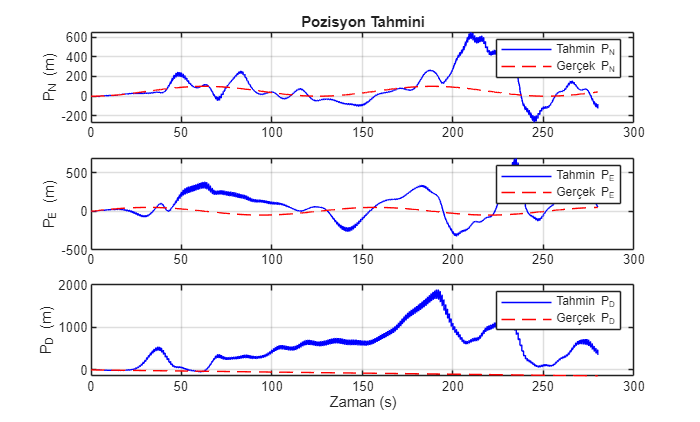


%% 8. Sonuçları Görselleştirme
% (Görselleştirme kodu bir önceki cevapta olduğu gibi kalabilir)
figure;
subplot(3,1,1); plot(time_vec, p_hat_hist(1,:), 'b', time_vec, p_true(1,:), 'r--'); legend('Tahmin P_N', 'Gerçek P_N'); ylabel('P_N (m)'); title('Pozisyon Tahmini'); grid on;
subplot(3,1,2); plot(time_vec, p_hat_hist(2,:), 'b', time_vec, p_true(2,:), 'r--'); legend('Tahmin P_E', 'Gerçek P_E'); ylabel('P_E (m)'); grid on;
subplot(3,1,3); plot(time_vec, p_hat_hist(3,:), 'b', time_vec, p_true(3,:), 'r--'); legend('Tahmin P_D', 'Gerçek P_D'); ylabel('P_D (m)'); xlabel('Zaman (s)'); grid on;

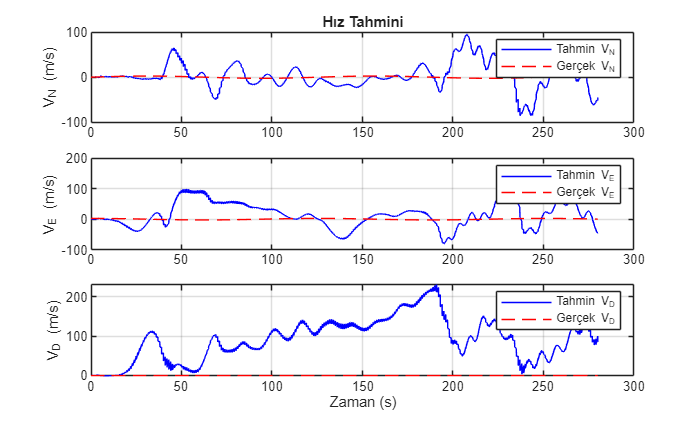


figure;
subplot(3,1,1); plot(time_vec, v_hat_hist(1,:), 'b', time_vec, v_true(1,:), 'r--'); legend('Tahmin V_N', 'Gerçek V_N'); ylabel('V_N (m/s)'); title('Hız Tahmini'); grid on;
subplot(3,1,2); plot(time_vec, v_hat_hist(2,:), 'b', time_vec, v_true(2,:), 'r--'); legend('Tahmin V_E', 'Gerçek V_E'); ylabel('V_E (m/s)'); grid on;
subplot(3,1,3); plot(time_vec, v_hat_hist(3,:), 'b', time_vec, v_true(3,:), 'r--'); legend('Tahmin V_D', 'Gerçek V_D'); ylabel('V_D (m/s)'); xlabel('Zaman (s)'); grid on;

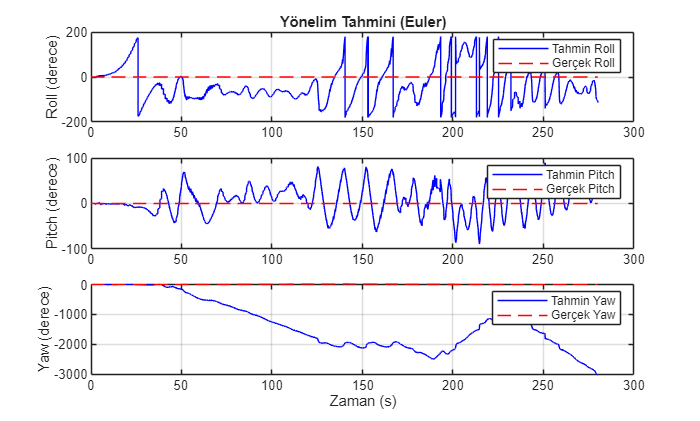


euler_hat_hist = zeros(3, num_steps);
euler_true_hist = zeros(3, num_steps);
for i = 1:num_steps
    Cbn_hat_i = q_to_Cbn(q_hat_hist(:,i));
    euler_hat_hist(1,i) = atan2(Cbn_hat_i(2,3), Cbn_hat_i(3,3));
    euler_hat_hist(2,i) = asin(-Cbn_hat_i(1,3));
    yaw_hat_val = atan2(Cbn_hat_i(1,2), Cbn_hat_i(1,1));
    if i > 1 % Yaw açısındaki sıçramaları düzelt (unwrapping)
        prev_yaw = euler_hat_hist(3,i-1);
        while (yaw_hat_val - prev_yaw) > pi
            yaw_hat_val = yaw_hat_val - 2*pi;
        end
        while (yaw_hat_val - prev_yaw) < -pi
            yaw_hat_val = yaw_hat_val + 2*pi;
        end
    end
    euler_hat_hist(3,i) = yaw_hat_val;

    Cbn_true_i = q_to_Cbn(q_true(:,i));
    euler_true_hist(1,i) = atan2(Cbn_true_i(2,3), Cbn_true_i(3,3));
    euler_true_hist(2,i) = asin(-Cbn_true_i(1,3));
    yaw_true_val = atan2(Cbn_true_i(1,2), Cbn_true_i(1,1));
     if i > 1 % Yaw açısındaki sıçramaları düzelt (unwrapping)
        prev_yaw_true = euler_true_hist(3,i-1);
        while (yaw_true_val - prev_yaw_true) > pi
            yaw_true_val = yaw_true_val - 2*pi;
        end
        while (yaw_true_val - prev_yaw_true) < -pi
            yaw_true_val = yaw_true_val + 2*pi;
        end
    end
    euler_true_hist(3,i) = yaw_true_val;
end

figure;
subplot(3,1,1); plot(time_vec, rad2deg(euler_hat_hist(1,:)), 'b', time_vec, rad2deg(euler_true_hist(1,:)), 'r--'); legend('Tahmin Roll', 'Gerçek Roll'); ylabel('Roll (derece)'); title('Yönelim Tahmini (Euler)'); grid on;
subplot(3,1,2); plot(time_vec, rad2deg(euler_hat_hist(2,:)), 'b', time_vec, rad2deg(euler_true_hist(2,:)), 'r--'); legend('Tahmin Pitch', 'Gerçek Pitch'); ylabel('Pitch (derece)'); grid on;
subplot(3,1,3); plot(time_vec, rad2deg(euler_hat_hist(3,:)), 'b', time_vec, rad2deg(euler_true_hist(3,:)), 'r--'); legend('Tahmin Yaw', 'Gerçek Yaw'); ylabel('Yaw (derece)'); xlabel('Zaman (s)'); grid on;

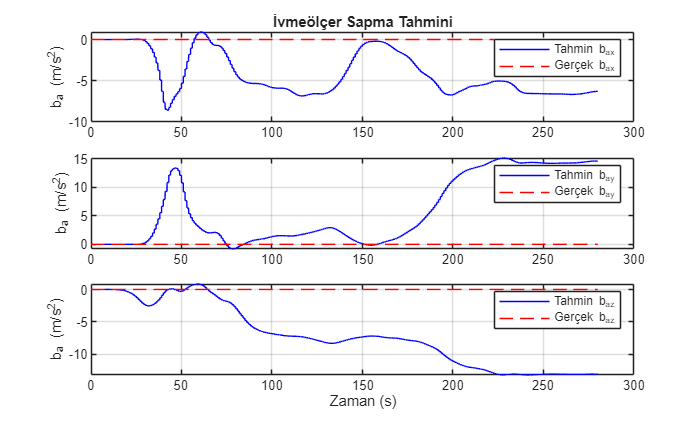


figure;
subplot(3,1,1); plot(time_vec, b_a_hat_hist(1,:), 'b', time_vec, ones(1,num_steps)*b_a_actual(1), 'r--'); legend('Tahmin b_{ax}', 'Gerçek b_{ax}'); ylabel('b_a (m/s^2)'); title('İvmeölçer Sapma Tahmini'); grid on;
subplot(3,1,2); plot(time_vec, b_a_hat_hist(2,:), 'b', time_vec, ones(1,num_steps)*b_a_actual(2), 'r--'); legend('Tahmin b_{ay}', 'Gerçek b_{ay}'); ylabel('b_a (m/s^2)'); grid on;
subplot(3,1,3); plot(time_vec, b_a_hat_hist(3,:), 'b', time_vec, ones(1,num_steps)*b_a_actual(3), 'r--'); legend('Tahmin b_{az}', 'Gerçek b_{az}'); ylabel('b_a (m/s^2)'); xlabel('Zaman (s)'); grid on;

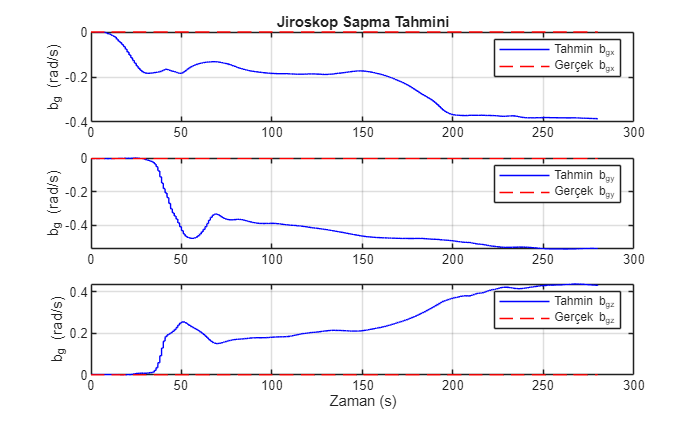


figure;
subplot(3,1,1); plot(time_vec, b_g_hat_hist(1,:), 'b', time_vec, ones(1,num_steps)*b_g_actual(1), 'r--'); legend('Tahmin b_{gx}', 'Gerçek b_{gx}'); ylabel('b_g (rad/s)'); title('Jiroskop Sapma Tahmini'); grid on;
subplot(3,1,2); plot(time_vec, b_g_hat_hist(2,:), 'b', time_vec, ones(1,num_steps)*b_g_actual(2), 'r--'); legend('Tahmin b_{gy}', 'Gerçek b_{gy}'); ylabel('b_g (rad/s)'); grid on;
subplot(3,1,3); plot(time_vec, b_g_hat_hist(3,:), 'b', time_vec, ones(1,num_steps)*b_g_actual(3), 'r--'); legend('Tahmin b_{gz}', 'Gerçek b_{gz}'); ylabel('b_g (rad/s)'); xlabel('Zaman (s)'); grid on;

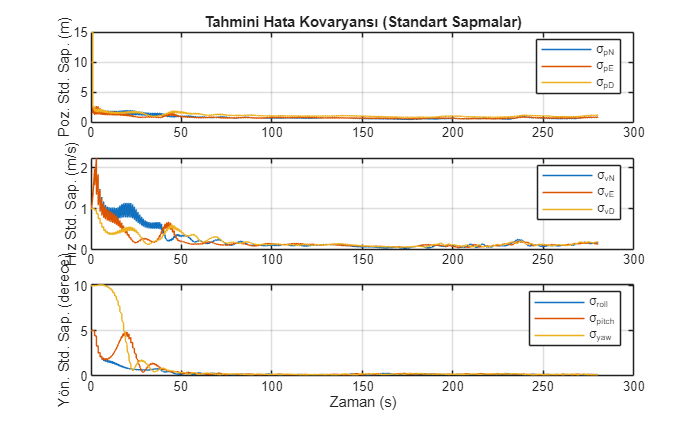


figure;
subplot(3,1,1); plot(time_vec, sqrt(P_diag_hist(1:3,:))'); legend('σ_{pN}','σ_{pE}','σ_{pD}'); ylabel('Poz. Std. Sap. (m)'); title('Tahmini Hata Kovaryansı (Standart Sapmalar)'); grid on;
subplot(3,1,2); plot(time_vec, sqrt(P_diag_hist(4:6,:))'); legend('σ_{vN}','σ_{vE}','σ_{vD}'); ylabel('Hız Std. Sap. (m/s)'); grid on;
subplot(3,1,3); plot(time_vec, rad2deg(sqrt(P_diag_hist(7:9,:))')); legend('σ_{roll}','σ_{pitch}','σ_{yaw}'); ylabel('Yön. Std. Sap. (derece)'); xlabel('Zaman (s)'); grid on;